# **各向同性的静磁隐形装置**

**        如图一所示，这是一种双层柱状结构，中心圆柱采用超导材料构成，即**$\mu_1 =0$，**从而任何磁场进入不到柱体内部；超导材料外部是一个内外半径分别为a和b的柱套，其磁导率为**$\mu_2$**。当在背景材料(**$\mu_b$**)中施加一个垂直于柱轴方向的匀强磁场**$H_0$**时，该磁场不会受到任何扰动，就像背景材料中没有任何东西一样，这种套层结构就是静磁情形下的隐形装置。**

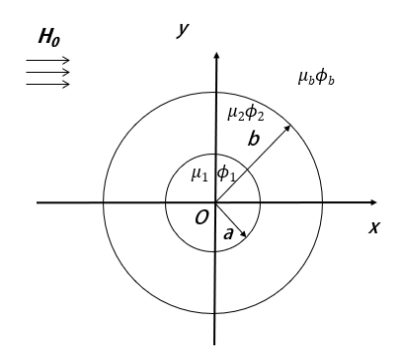

**        与**[**静电型隐身衣的设计推导**](matlab:open('..\B 第二章 静电场\B4_Electrostatic _Invisibility_Cloak.mlx'))**类似，上述问题可采用电、磁比拟的方法，设静磁隐形衣周围的磁标势分布**$\phi_b =\left(-H_0 r+\frac{D}{r}\right)\cos \varphi$，**则D可以利用边界条件匹配得到。假设需要隐身处理的材料为超导材料**$\mu_1 =0$，**则D可以简化为**


$$D=H_0 b^2 \frac{\left(b^2 -a^2 \right)\mu_2^2 -\left(b^2 +a^2 \right)\mu_2^{\;} \mu_b^{\;} }{\left(b^2 -a^2 \right)\mu_2^2 +\left(b^2 +a^2 \right)\mu_2^{\;} \mu_b^{\;} }=H_0 b^2 \frac{\left(b^2 -a^2 \right)\mu_2^{\;} -\left(b^2 +a^2 \right)\mu_b^{\;} }{\left(b^2 -a^2 \right)\mu_2^{\;} +\left(b^2 +a^2 \right)\mu_b^{\;} }$$


**        如果要实现隐形的功能，则 D=0，于是**


$$\mu_2^{\;} =\frac{b^2 +a^2 }{b^2 -a^2 }\mu_b^{\;}$$


**        或者**


$${b^2 =a}^2 \frac{\mu_2^{\;} +\mu_b^{\;} }{\mu_2^{\;} -\mu_b^{\;} }$$


**        因此，若要实现这种静磁“隐形装置”，其套层材料或者其几何结构必须满足上两式。具体应用的时候，需要隐藏的物体可以放置在超导材料内部而不被外界探测到。**

**       定义参数：**

超导柱半径：

a=0.4;

柱套层半径：

b=0.5;

计算可得柱套层的介电常数为：

u2=(b^2+a^2)/(b^2-a^2)

u2 = 4.5556

**       用pdetool仿真：**

- **仅有超导柱时的磁势分布仿真**

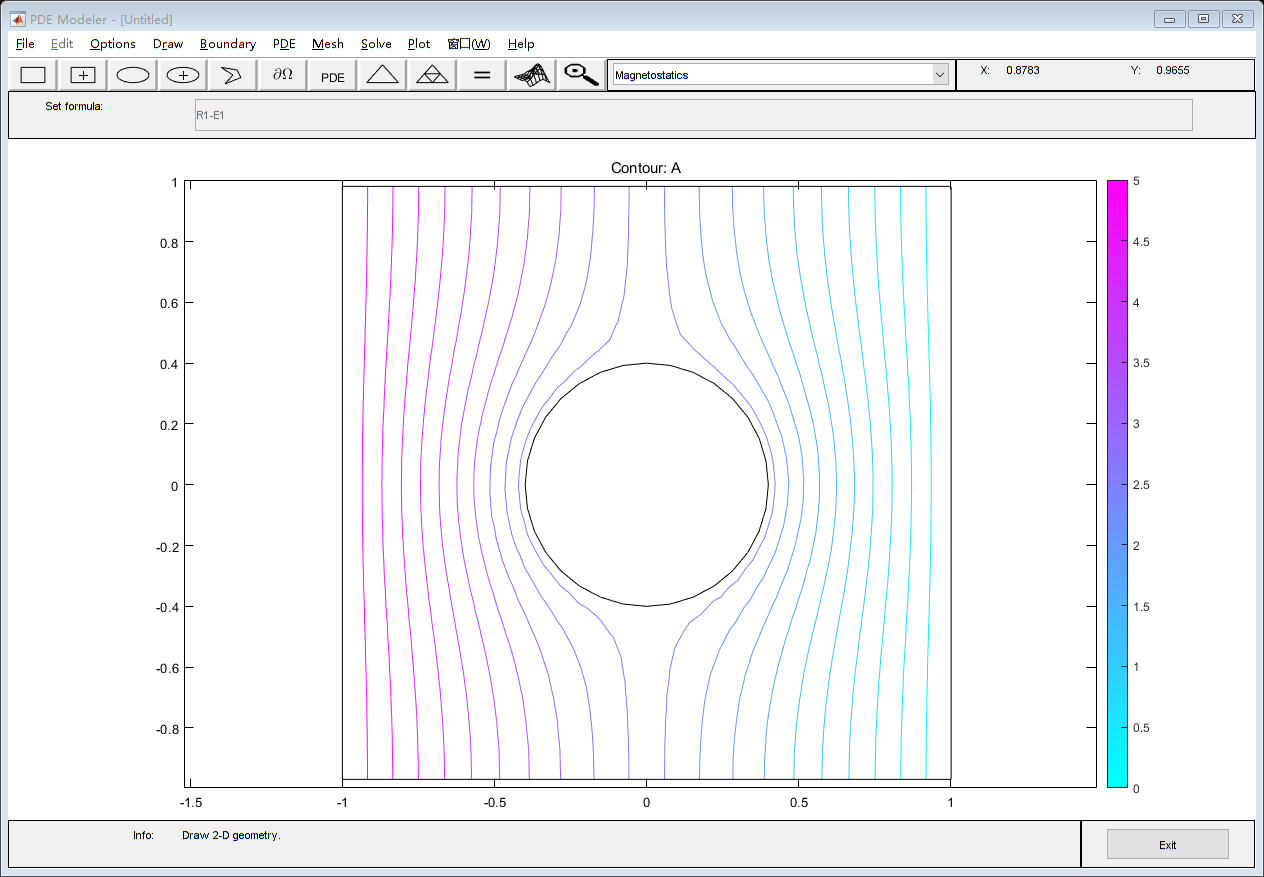

Without_Invisibility_Cloak(a)

- **用隐形材料包裹超导柱时的磁势分布**

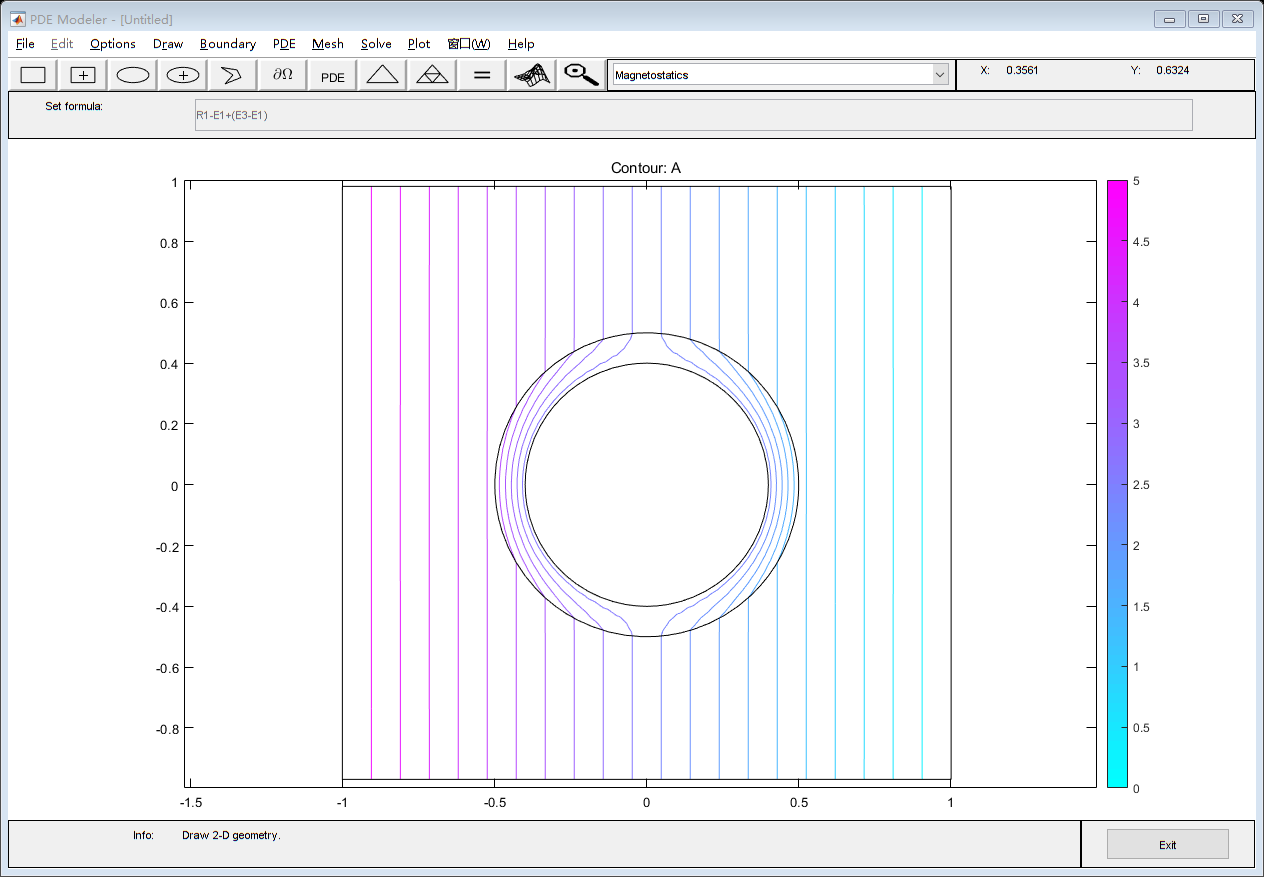

With_Invisibility_Cloak(a,b,u2)

function With_Invisibility_Cloak(a,b,u2)
    u = ['1.0!', num2str(u2)];
    uu = ['1./(1.0)!1./(',num2str(u2),')'];
    current_density='0!0';
    % Make the string lengths equal
    current_density = [current_density, blanks(length(u) - length(current_density))];

    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',6);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5000000000000002 1 1.0000000000000002]);
    set(ax,'XLim',[-1.5222222222222224 1.4777777777777779]);
    set(ax,'YLim',[-0.99753086493339027 1.0024691350666095]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1.0012345679012349 1.0012345679012347 0.9814814814814814 -0.96913580246913567],'R1');
    pdeellip(0,0,a,a,...
    0,'E1');
    pdeellip(0,0,b,b,...
    0,'E3');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1-E1+(E3-E1)')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(8,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(7,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(6,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(5,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    uu,...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    [u;...
    current_density])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1956','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 0 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end

function Without_Invisibility_Cloak(a)
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',6);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5000000000000002 1 1.0000000000000002]);
    set(ax,'XLim',[-1.5222222222222224 1.4777777777777779]);
    set(ax,'YLim',[-0.99753086493339027 1.0024691350666095]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1.0012345679012349 1.0012345679012347 0.9814814814814814 -0.96913580246913567],'R1');
    pdeellip(0,0,a,a,...
    0,'E1');

    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1-E1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(8,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(7,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(6,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(5,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1./(1.0)!1./(1)',...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0!1';...
    '0!0  '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1956','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 0 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end